This function creates a filter that can be applied on a signal to compensate for chromatic dispersion

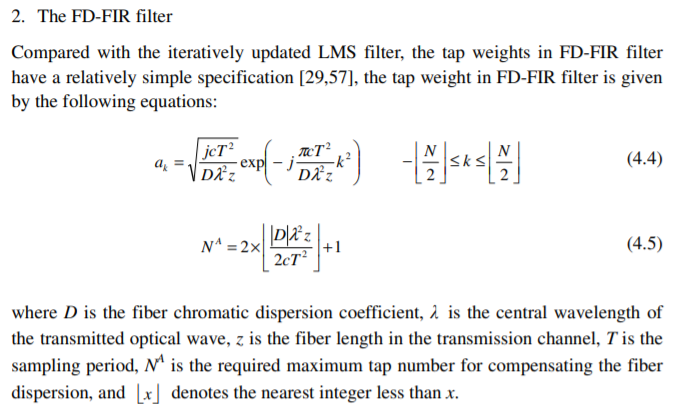

Requires chromatic dispersion coefficient D, wavelength $\lambda$, fiber length z, sampling period T, and max tap number N.

//Hard coded values for simplicity: D, z, $\lambda
$ where D = 16ps/nm/km (typically for optical comms), z = 5000km, $\lambda$ = 1550nm//

function CD_FD_FIR = CD_Filter(sample_rate,D,z,l)

lecture = false;

%D = 16*10^(-6); %s/m/m
%z = 5000e3;
lambda = l; %1550*10^(-9);
T = 1/sample_rate;
c = 299792458; % m/s

if lecture
    CD_FD_FIR = Lectures(sample_rate,D,z,l);

else
    N = 2*(2*floor((D*z*lambda^2)/(2*c*T^2))) + 1;

    k_sqr = (-floor(N/2):floor(N/2)).^2;

    a_k_amplitude = sqrt((1j*c*T^2)/(D*z*lambda^2));

    a_k_exp = (-1j*pi*c*T^2)/(D*z*lambda^2);

    CD_FD_FIR = a_k_amplitude * exp((a_k_exp * k_sqr));

    end

end

function CD_FIR = Lectures(sample_rate,D,z,l)

%% D = -(2πc/λ^2)β2 => -(Dλ^2)/(2πc) = β2


%Ignoring the sign change since we find absolute value regardless

c = 299792458; % m/s

beta_2 = (D*l^2)/(2*pi*c);

T = 1/sample_rate;

M = floor(pi*beta_2*z/(T^2));

k = (-M:M);

CD_FIR = ifftshift(ifft(exp(1j*ifftshift(k).^2/(M*2/pi))));
CD_FIR = 1/sqrt(2*M)*exp(-1j*pi/(2*M)*k.^2);

end